# 1.3.12. Ускорение расчетов

**Практическое занятие**

Оптимизируйте алгоритм расчета интеграла методом [Монте-Карло](https://ru.wikipedia.org/wiki/%D0%9C%D0%B5%D1%82%D0%BE%D0%B4_%D0%9C%D0%BE%D0%BD%D1%82%D0%B5-%D0%9A%D0%B0%D1%80%D0%BB%D0%BE)

## Суть метода

Вычисление интеграла методом Монте-Карло подразумевает вычисление площади под кривой следующим образом:

1. Задание прямоугольной области вокруг диапазона интегрирования 

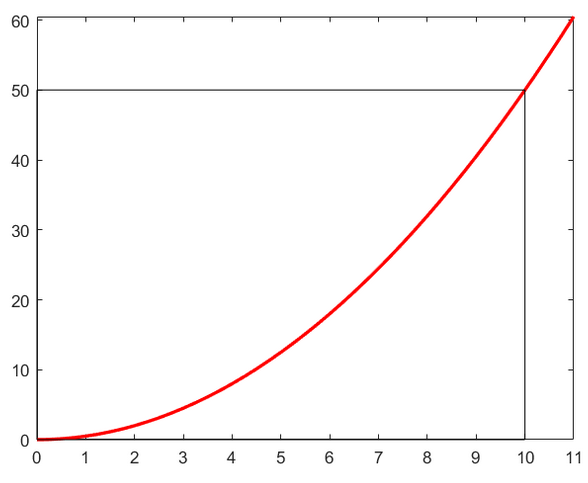

2. Заполнение этой области большим количеством точек в случайном порядке

 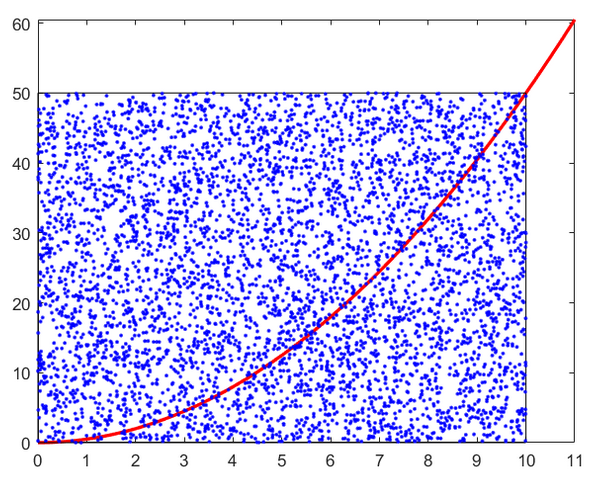

3. Поиск точек, которые лежат под кривой

 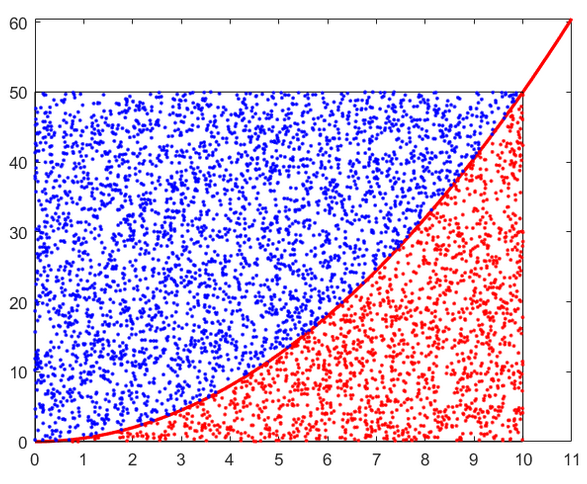

4. Подсчет количества точек под кривой

5. Расчет площади по формуле:

$S=S_0 *\frac{n}{N}$,

где   $S$ - искомый интеграл (площадь под кривой),

        $S_0$ - площадь прямоугольной области,

        $N$ - общее количество точек

        $n$ - количество точек под кривой

## Постановка задачи

Функция `f(x)`, которую нужно проинтегрировать,  задана ввиде локальной функции в конце этого скрипта.

Визуализируем её

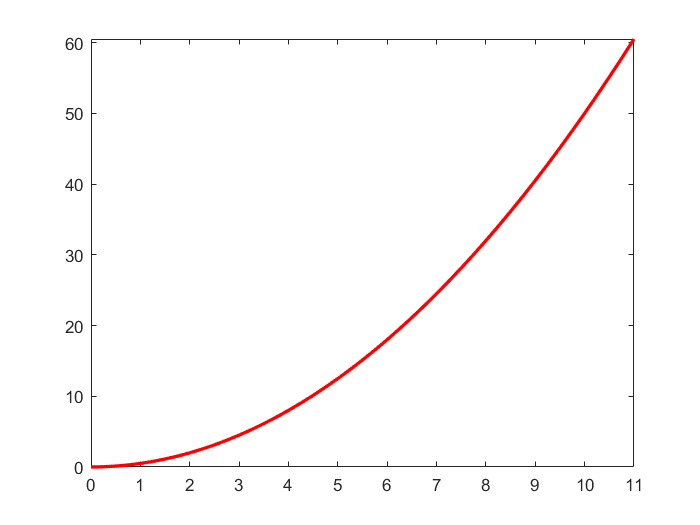

figure
fplot(@f, [0 11], 'r', 'LineWidth', 2)

Зададим пределы интегрирования

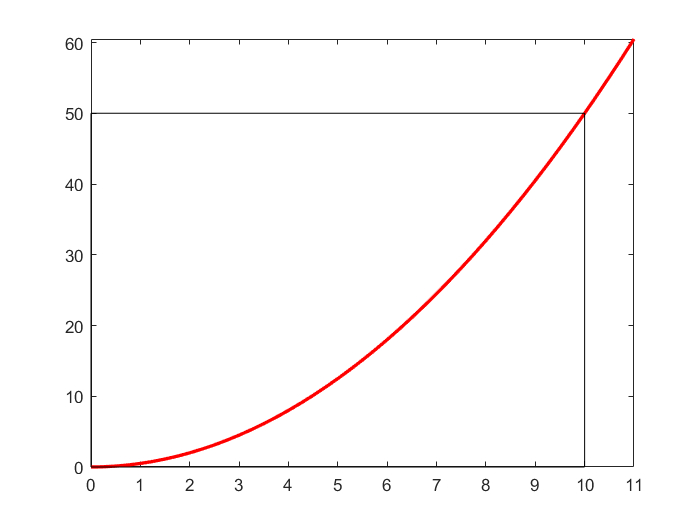

x1 = 0;
y1 = 0;
x2 = 10;
y2 = f(x2);
rectangle('Position',[x1 y1 x2 y2])

## Реализация метода

Зададим количество случайных точек

N = 5000;

И сгенерируем матрицу `a` случайных значений. Первый столец `a` - абсциссы точек, второй столбец - ординаты

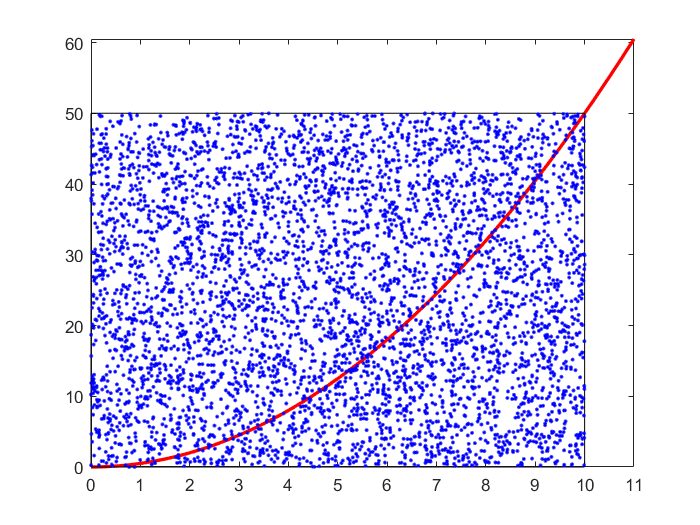

a = rand(N, 2);
a(:, 1) = a(:, 1) * x2;
a(:, 2) = a(:, 2) * y2;
hold on
scatter(a(:,1), a(:,2), '.b');

### Поиск точек под графиком (способ 1)

Это самая ресурсоемкая часть метода. Из всего множества точек надо отобрать только те, кторые лежат по кривой.

Первый способ, который описан ниже, работает, но реализован неоптимально. Внимательно изучите алгоритм, потому что дальше вам нужно будет его оптимизировать

Засечём время выполнения

tic

В цикле (`for`) переберем все точки, и в переменную `b` запишем только те, которые лежат под кривой (`if`). В переменную n запишем количество таких точек

b = []; % Инициализация матрицы искомых точек (на всякий случай)
n = 0; % Инициализация количества искомых точек
for i = 1 : N % Для каждой исходной точки
    if a(i, 2) <= f(a(i, 1)) % сравниваем её с кривой, и если точка лежит под ней
        n = n + 1; % учитываем найденную точку
        b(n, :) = a(i, :); % сохраняем найденную точку
    end
end

Посмотрим время выполнения

toc

Elapsed time is 0.066201 seconds.


Выполните скрипт (F5) и обратите внимание на время выполнения приведенного алгоритма. Затем поменяйте в скрипте значение переменной `N` с `5000` на `5e4`, `5e5`, `5e6`,... При каждом N выполните скрипт (F5) и отметьте увеличение количества точек на графике и многократное увеличение времени выполнения алгоритма.

Это время можно уменьшить, оптимизировав алгорим поиска точек под кривой.

### Поиск точек под графиком (способ 2)

Оптимизируйте приведенный выше алгоритм.

Засечём время выполнения

tic

У приведенного алгоритма есть существенная проблема - размер переменной `b` меняется на каждой итерации цикла. Вначале `b` это пустая матрица высотой `0`, но на каждой итерации к ней добавляется новая точка и высота увеличивается на `1`.

Из-за этого на каждой итерации цикла затрачивается дополнительное время на выделение большего количества оперативной памяти компьютера для хранения `b`. А поскольку метод Монте-Карло предполагает большое количество итераций (до миллионов и больше), это время суммируется и работа алгоритма может замедляться в разы. 

Не смотря на то, что проблема не связана напрямую с самим алгоритмом, а связана с тем, как он выполняется на компьютере, немного изменив алгоритм, от неё можно избавиться.

Чтобы ускорить алгоритм нужно избежать переопределения размера `b` на каждой итерации цикла. Для этого нужно выделить память для переменной один раз и сразу много. Нужно перед циклом инициализировать её не пустым вектором, а сразу вектором нужной или большей (если мы не знаем нужный размер) длины.

**Вам нужно проделать следующее:**

- Скопируйте в поле ниже код алгоритма из предыдущего раздела (способ 1)

- Инициализируйте переменную `b` перед циклом нулями таким образом, чтобы её размер не изменялся на каждой итерации цикла. Учтите, что заранее количество искомых точек `n` и высоту матрицы `b` мы предсказать не можем, но зато точно можем сказать, что количество искомых точек `n` не может быть больше, чем количество исходных точек `N`

- После завершения цикла удалите из матрицы `b` пустые значения, которые были инициализированы, но не заполнились

b = zeros(N, 2); % Инициализация матрицы искомых точек нулями
n = 0; % Инициализация количества искомых точек
for i = 1 : N % Для каждой исходной точки
    if a(i, 2) <= f(a(i, 1)) % сравниваем её с кривой, и если точка лежит под ней
        n = n + 1; % учитываем найденную точку
        b(n, :) = a(i, :); % сохраняем найденную точку
    end
end
b = b(1:n, :); % удаление лишних незаполненных значений

Посмотрим время выполнения

toc

Elapsed time is 0.070596 seconds.


Поиграйте с количеством исходных точек `N` и оцените ускорение влгоритма в разы при большом количестве точек.

### Поиск точек под графиком (способ 3)

На самом деле, матричные возможности среды MATLAB позволяют переписать алгоритм поиска точек в две строки, которые выполняются на порядки быстрее. Помогут в этом такие техники как *векторизация* и *логическое индексирование*.

Засечём время выполнения

tic

Изучите локальную функцию `f(x)` в конце скрипта и обратите внимание, что она векторизована. То есть, если на вход за раз подать обсциссы всех точек, на выходе получим ординаты всех точек. Отюда следует первый вывод:

*Цикл *`for`*, который применяет одну и ту же функцию к каждому элементу вектора, можно заменить одним вызовом функции для целого вектора (если функция векторизована)*

Но функция `f(a)` не просто вызывается на каждой итерации цикла, результат её вызова используется при проверке условия (`<=`), при выполнении которого из `a` выбирается точка. То есть в цикле происходит выборка из матрицы `a` значений по определенному условию. Эту задачу, как вы знаете, решает логическое индексирование. Второй вывод:

*Если из массива нужно по какому-то условию выбрать определенные элементы, вместо конструкции *`for`*-*`if`* проще применить логическое индексирование.*

Учитывая эти два обстоятельства, перепишите алгоритм поиска точек более оптимально. Ни инициализации переменных, ни цикла `for`, ни конструкции `if` в алгоритме остаться не должно. Для этого нужно написать две строчки кода:

- В первой получите `b` с помощью логического индексирования и вызова функции `f()` от всего первого столбца матрицы `a` (подсказка: правильно модифицируйте условие `a(i, 2) <= f(a(i, 1))`)

- Во второй строчке запишите в переменную `n` количество найденных точек (подсказка: `size(...,...)`)

b = a(a(:,2) <= f(a(:, 1)), :);
n = size(b, 1);

Посмотрим время выполнения

toc

Elapsed time is 0.011445 seconds.


Такой алгоритм не просто компактнее, он выполняется на порядки быстрее и может сэкономить часы вашего времени. Не пренебрегайте мощными особенностями MATLAB.

### Вычисление площади

Визуализируем найденные точки под кривой

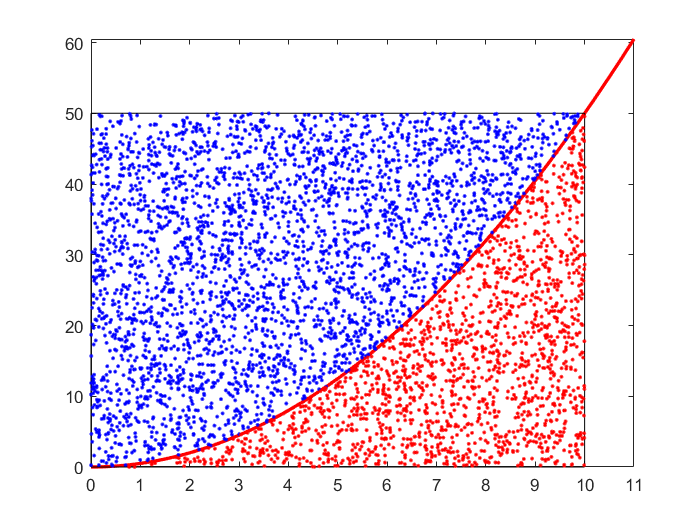

scatter(b(:,1), b(:,2), '.r');
hold off

Вычислим площадь под графиком

S0 = x2*y2;
S = S0 * n / N;
fprintf('Интеграл функции в диапазоне %d..%d составляет: %3.3f', x1, x2, S)

Интеграл функции в диапазоне 0..10 составляет: 169.900

Проверим результат расчёта встроенными в MATLAB численными методами

S1 = integral(@f, x1, x2);
fprintf('Результат численного интегрирования: %3.3f', S1)

Результат численного интегрирования: 166.667

Функция, которую необходимо интегрировать

function y = f(x)
% Обратите внимание, что функция приспособлена для работы с векторами (.^)
% Векторизация позволяет удобнее работать с функцией, а также применять
% встроенные в MATLAB численные методы интегрирования
y = 0.5*x.^2;
end

*2018 © ЦИТМ Экспонента*